clc; clear all; close all;
run('variableLoader.m')
%INPUTS
sim('inputs.slx');

load('doublet.mat')
input = doublet;
Ts = 0.02;
iodelay = 0;

# SIMO identification - short period mode(5secs)

paramStruct.StopTime = "5";

## elevator input

out = sim('elevator',paramStruct);

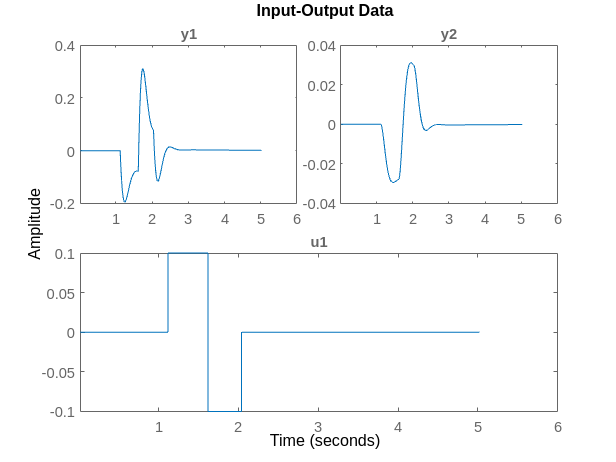

u = out.elevator;
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 2];
nz = [1; 1];
data = iddata(y,u,Ts);
plot(data)

sys_el_1= tfest(data,np,nz,iodelay)

sys_el_1 =
  From input "u1" to output...
          -36.96 s - 126.8
   y1:  ---------------------
        s^2 + 14.41 s + 139.9
 
         -0.03535 s - 37.66
   y2:  ---------------------
        s^2 + 14.44 s + 141.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;2]   Number of zeros: [1;1]
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [96.58;97.56]%           
FPE: 1.289e-14, MSE: 6.661e-06                   
 
Model Properties


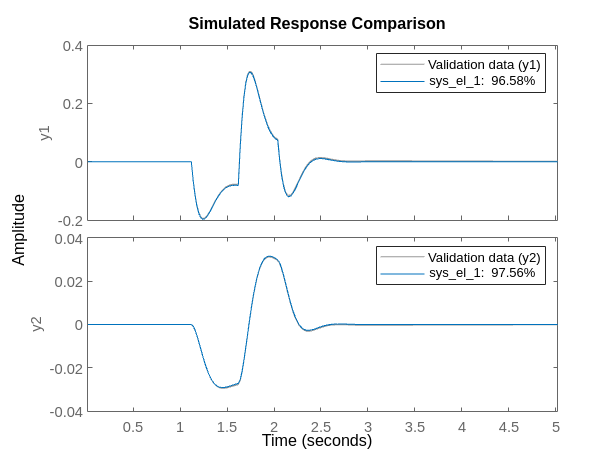

compare(data,sys_el_1)

# SIMO identification - Phugoid mode(20secs)

paramStruct.StopTime = "20";

## elevator input

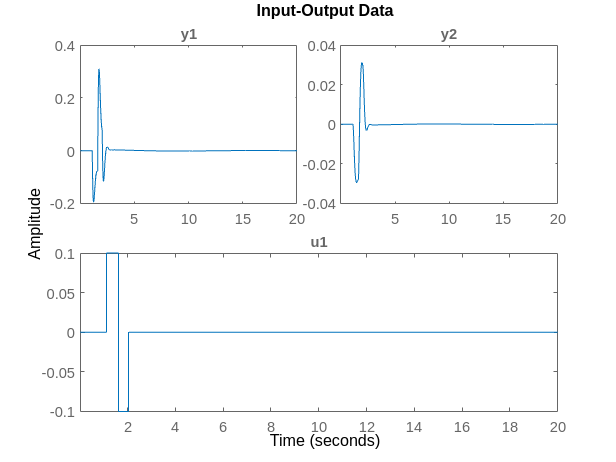

out = sim('elevator',paramStruct);
u = out.elevator;
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 2];
nz = [1; 1];
data = iddata(y,u,Ts);
plot(data)

sys_el_2= tfest(data,np,nz,iodelay)

sys_el_2 =
  From input "u1" to output...
          -36.96 s - 126.7
   y1:  ---------------------
        s^2 + 14.41 s + 139.9
 
         -0.03549 s - 37.66
   y2:  ---------------------
        s^2 + 14.44 s + 141.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;2]   Number of zeros: [1;1]
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [96.18;97.26]%           
FPE: 9.819e-16, MSE: 2.084e-06                   
 
Model Properties


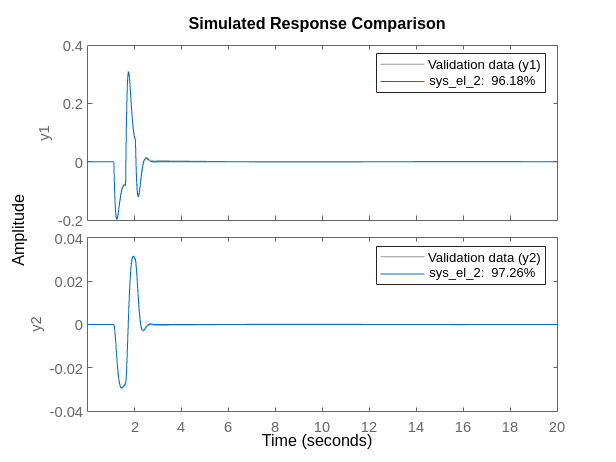

compare(data,sys_el_2)

## throttle input

out = sim('throttle',paramStruct);

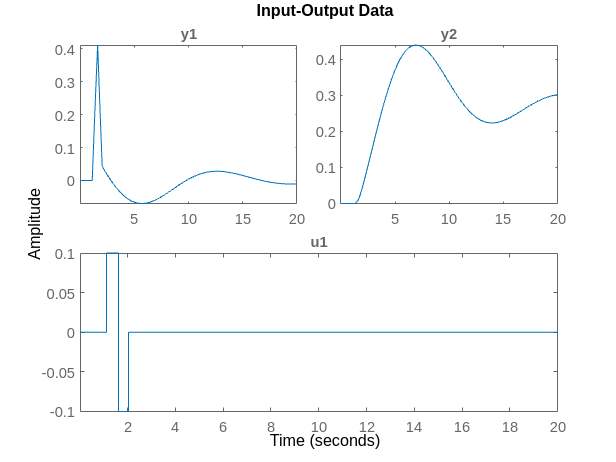

u = out.throttle;
y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
%y3 = squeeze(out.pitch_rate);
%y4 = squeeze(out.aoa)-alpha_trim;
y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y1 y5];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 3];
nz = [1; 2];
data = iddata(y,u,Ts);
plot(data)

sys_t= tfest(data,np,nz,iodelay)

sys_t =
  From input "u1" to output...
            8.65 s + 2.259
   y1:  ----------------------
        s^2 + 0.2402 s + 0.218
 
             -0.4337 s^2 - 1.096 s + 2.05
   y2:  --------------------------------------
        s^3 + 0.2592 s^2 + 0.222 s + 0.0004215
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;3]   Number of zeros: [1;2]
   Number of free coefficients: 10
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [96.09;98.27]%           
FPE: 4.223e-12, MSE: 9.964e-06                   
 
Model Properties


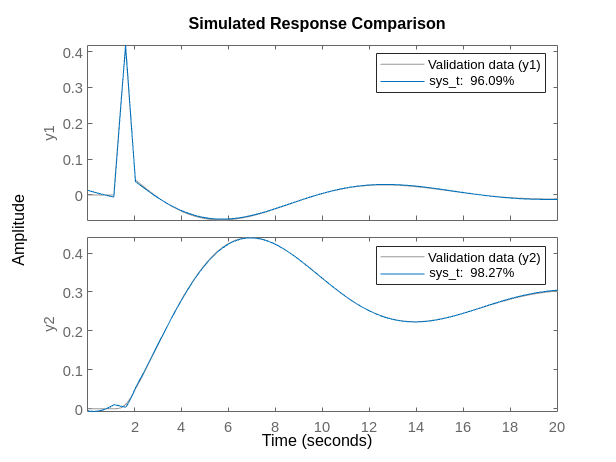

compare(data,sys_t)

sim('inputs.slx');
load('doublet.mat')
load('doublet2.mat')
load('doublet3.mat')
Ts = 0.02;
iodelay = 0;

# MIMO identification - short period mode(20secs)

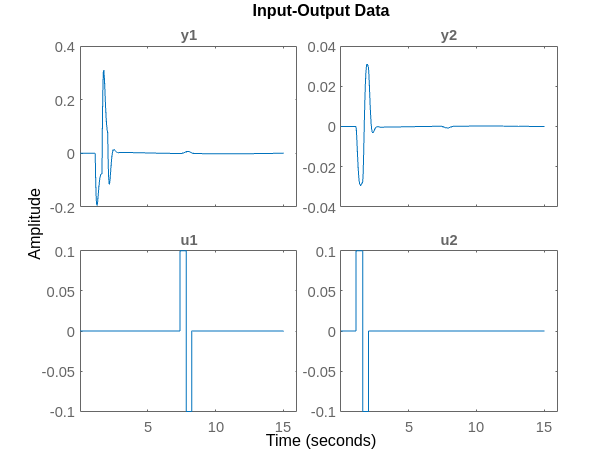

paramStruct.StopTime = "15";
input = doublet2;  %elevator
input2 = doublet;  %throttle
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [3 3; 2 2];
nz = [2 2; 1 1];
data = iddata(y,u,Ts);
plot(data)

sys1= tfest(data,np,nz,iodelay)

sys1 =
  From input "u1" to output...
           -0.3384 s^2 + 3.1 s - 1.755
   y1:  ---------------------------------
        s^3 + 18.42 s^2 + 1.667 s + 2.296
 
         -0.01956 s + 0.002917
   y2:  ------------------------
        s^2 + 0.08458 s + 0.2061
 
  From input "u2" to output...
            -36.24 s^2 - 132.4 s + 24.11
   y1:  -------------------------------------
        s^3 + 14.26 s^2 + 143.1 s + 5.006e-11
 
         -0.03475 s - 37.64
   y2:  ---------------------
        s^2 + 14.43 s + 141.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 3;2 2]   Number of zeros: [2 2;1 1]
   Number of free coefficients: 20
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [98.47;98.59]%           
FPE: 3.379e-15, MSE: 4.516e-07                   
 


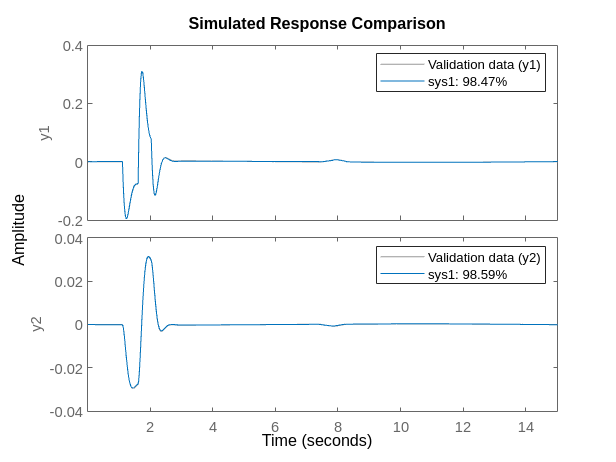

compare(data,sys1)

# MIMO identification - Phugoid mode(20secs)

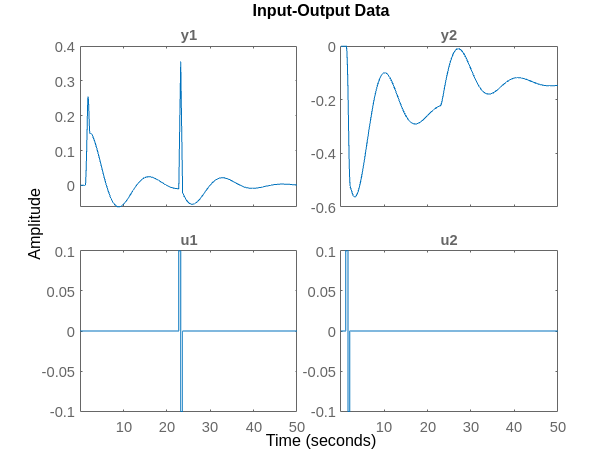

paramStruct.StopTime = "50";
input = doublet3;  %elevator
input2 = doublet;  %throttle
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
%y3 = squeeze(out.pitch_rate);
%y4 = squeeze(out.aoa)-alpha_trim;
y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y1 y5];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [3 3; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u,Ts);
plot(data)

sys2= tfest(data,np,nz,iodelay)

sys2 =
  From input "u1" to output...
                 -4514 s - 1941
   y1:  ---------------------------------
        s^3 + 699.7 s^2 + 303.7 s + 197.8
 
             1.49 s^2 + 2.887 s + 7.911
   y2:  ------------------------------------
        s^3 + 0.6205 s^2 + 0.3337 s + 0.0708
 
  From input "u2" to output...
                 19.29 s + 12.46
   y1:  ----------------------------------
        s^3 + 2.999 s^2 + 0.5447 s + 0.433
 
             2.056 s^2 - 20.58 s - 1.233
   y2:  --------------------------------------
        s^3 + 0.1515 s^2 + 0.2026 s + 0.003356
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [3 3;3 3]   Number of zeros: [1 1;2 2]
   Number of free coefficients: 22
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [-5.324;54.84]%          
FPE: 8.728e-06, MSE: 0.005927       

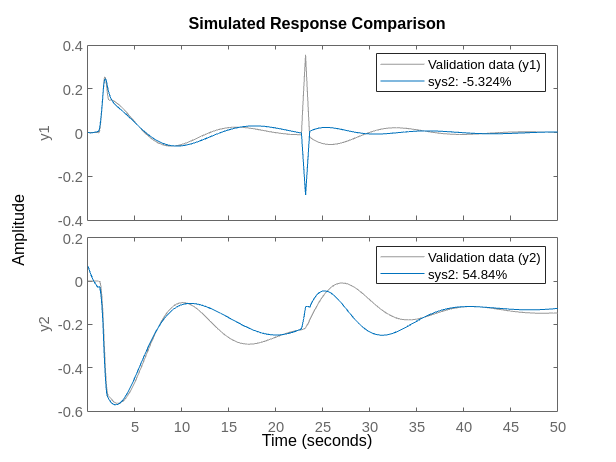

compare(data,sys2)